% This script generates parameter data required 
% for the solar panel Simulink models.
%
% Copyright 2020 The Mathworks, Inc.

format long
% Motor parameters *{Motor variables came from DB-4000 Matrix Series}*
Kg = 2;                % Gear ratio, []
Ke = 0.469*Kg            % Back EMF cosntant, [V/(rad/s)]

Ke =    0.938000000000000


Kt = 0.4695*Kg           % Torque constant, [N*m/A]

Kt =    0.939000000000000


Lm = 3.2/1000            % Inductance, [H]

Lm =    0.003200000000000


Rm = 0.98               % Resistance, [Ohm]

Rm =    0.980000000000000


Kd = 73.214*Kg^2/50        % Damping constant, [N*m/(rad/s)]

Kd =    5.857120000000000




% Solar panel parameters 
m = 28.5;               % Mass, [kg]
w = 1.134;              % Width, [m]
l = 2.279;              % Length, [m]
h = 0.035;              % Depth, [m]
A = w*l;                % Area, [m^2]
beta = pi/6;            % Elevation angle, [rad]
J = 1/12*m*(w^2+h^2*sin(beta)^2+l^2*cos(beta)^2) + 0.0071*Kg^2 % Inertia, [kg*m^2]

J =   12.334802125000000



%Spring
Ks =2876.878385/1000; %spring constant (Nm/rad)

%Wind
U = 3.6; %Wind speed
rho = 1.09; %density 
Cd = 1.17; %drag coefficient
r = 0.5*w; 
L = l;

%Coeefecients
Num = Kt/(J*Lm)  %numerator

Num =   23.789396621553021


C = 2/3*rho*r^3*Cd*l*U*sin(beta)*abs(sin(1.1019))+Kd;
s3 = 1

s3 =      1


s2 = (Rm/Lm)+ (C/J)

s2 =      3.067708233472935e+02


s1 = (Rm*C+Ke*Kt+Lm*Ks)/(J*Lm)

s1 =      1.820498367732776e+02


s0 = (Rm*Ks)/(Lm*J)

s0 =   71.427494051206764


Denom = [s3 s2 s1 s0]

Denom = 1.0e+02 *

   0.010000000000000   3.067708233472934   1.820498367732776   0.714274940512068




% Generate nyquist plot
Q = tf(Num,Denom)

Q =
 
               23.79
  -------------------------------
  s^3 + 306.8 s^2 + 182 s + 71.43
 
Continuous-time transfer function.
Model Properties


% Poles = roots(Denom)
pole(Q)

ans = 1.0e+02 *

 -3.061769950994572 + 0.000000000000000i
 -0.002969141239180 + 0.003809596418097i
 -0.002969141239180 - 0.003809596418097i


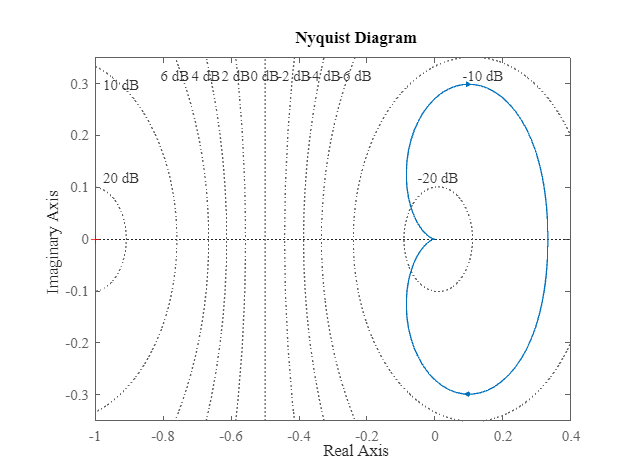

nyquistplot(Q), grid
ylim([-0.35 0.35])
fontname("Times New Roman",11)

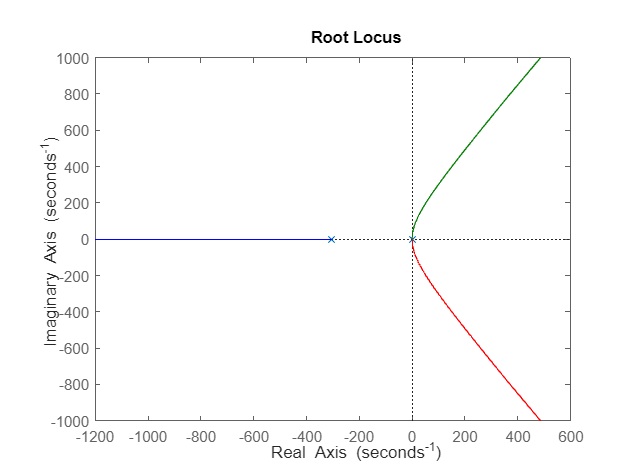


rlocus(Q)

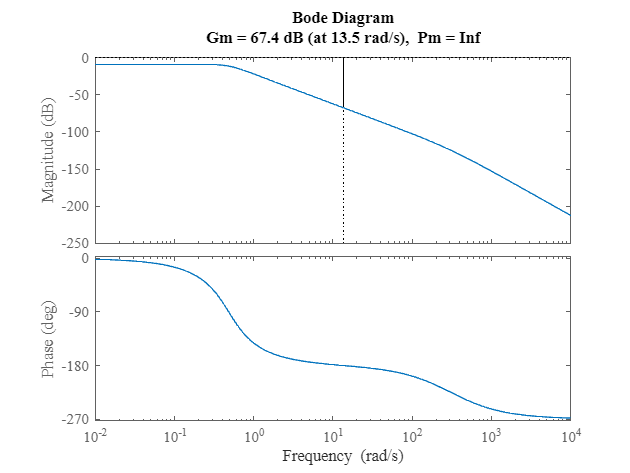

margin(Q)
fontname("Times New Roman",15)